# SNW_DS_PARAM Base Solution Analysis

This is the example vignette for function: [**snw_ds_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_ds_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for vfi and gets distribution induced by policy functions and exogenous distributions. Base Simulations.

## Test SNW_DS_MAIN Defaults Base

Call the function with testing defaults. Note:

- mean of a_ss = mp_dsvfi_results('A_agg')/sum(Phi_true,'all')

- mean of c_ss = (mp_dsvfi_results('Y_inc_agg') - mp_dsvfi_results('Tax_revenues'))/sum(Phi_true,'all')

mp_params = snw_mp_param('default_base');
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = true;
mp_controls('bl_print_ds') = true;
mp_controls('bl_print_vfi_verbose') = false;
mp_controls('bl_print_ds_verbose') = false;
mp_controls('bl_vfi_store_all') = true;
mp_controls('bl_ds_store_all') = true;
[mp_dsvfi_results] = snw_ds_main(mp_params, mp_controls);

SNW_VFI_MAIN: Finished Age Group:42 of 42
SNW_VFI_MAIN: Finished Age Group:41 of 42
SNW_VFI_MAIN: Finished Age Group:40 of 42
SNW_VFI_MAIN: Finished Age Group:39 of 42
SNW_VFI_MAIN: Finished Age Group:38 of 42
SNW_VFI_MAIN: Finished Age Group:37 of 42
SNW_VFI_MAIN: Finished Age Group:36 of 42
SNW_VFI_MAIN: Finished Age Group:35 of 42
SNW_VFI_MAIN: Finished Age Group:34 of 42
SNW_VFI_MAIN: Finished Age Group:33 of 42
SNW_VFI_MAIN: Finished Age Group:32 of 42
SNW_VFI_MAIN: Finished Age Group:31 of 42
SNW_VFI_MAIN: Finished Age Group:30 of 42
SNW_VFI_MAIN: Finished Age Group:29 of 42
SNW_VFI_MAIN: Finished Age Group:28 of 42
SNW_VFI_MAIN: Finished Age Group:27 of 42
SNW_VFI_MAIN: Finished Age Group:26 of 42
SNW_VFI_MAIN: Finished Age Group:25 of 42
SNW_VFI_MAIN: Finished Age Group:24 of 42
SNW_VFI_MAIN: Finished Age Group:23 of 42
SNW_VFI_MAIN: Finished Age Group:22 of 42
SNW_VFI_MAIN: Finished Age Group:21 of 42
SNW_VFI_MAIN: Finished Age Group:20 of 42
SNW_VFI_MAIN: Finished Age Group:1

## Show All Info in mp_dsvfi_results Base

ff_container_map_display(mp_dsvfi_results);

pos = 14 ; key = mp_cl_mt_xyz_of_s
  Map with properties:

        Count: 8
      KeyType: char
    ValueType: any

pos = 15 ; key = mp_controls
  Map with properties:

        Count: 18
      KeyType: char
    ValueType: any

pos = 16 ; key = mp_params
  Map with properties:

        Count: 29
      KeyType: char
    ValueType: any

----------------------------------------
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
CONTAINER NAME: mp_dsvfi_results ND Array (Matrix etc)
xxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxxx
                    i    idx    ndim      numel      rowN    colN        sum           mean          std        coe

## Base Param Results Define Frames Base

Define the matrix dimensions names and dimension vector values. Probability mass matrixes, Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 21:2:99, 100];
agrid = mp_params('agrid')';
eta_grid = mp_params('eta_grid')';
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_params('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'shock', eta_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Probability Mass Along Age Dimensions

Where are the mass at? Analyze mass given state space components.

% Get the Joint distribution over all states
Phi_true = mp_dsvfi_results('Phi_true');
Phi_true = Phi_true/sum(Phi_true(:));
% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Exogenous Permanent States Mass: Life Cycle, Edu and Marraige

Tabulate value and policies along savings and shocks:

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,5,4];
% Value Function
tb_prob_aem = ff_summ_nd_array("P(Age, EDU, MARRY))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, EDU, MARRY))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    marry    edu    sum_age_19    sum_age_21    sum_age_23    sum_age_25    sum_age_27    sum_age_29    sum_age_31    sum_age_33    sum_age_35    sum_age_37    sum_age_39    sum_age_41    sum_age_43    sum_age_45    sum_age_47    sum_age_49    sum_age_51    sum_age_53    sum_age_55    sum_age_57    sum_age_59    sum_age_61    sum_age_63    sum_age_65    sum_age_67    sum_age_69    sum_age_71    sum_age_73  

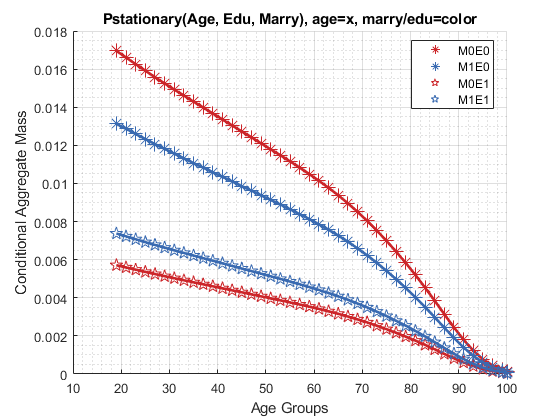

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Edu, Marry), age=x, marry/edu=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = ["M0E0", "M1E0", "M0E1", "M1E1"];
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
mp_support_graph('cl_scatter_shapes') = {'*', '*', 'p', 'p' };
mp_support_graph('cl_colors') = {'red', 'blue', 'red', 'blue'};
ff_graph_grid((tb_prob_aem{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

#### Kids and Marry By Age Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_prob_amarrykids = ff_summ_nd_array("P(Age, Kids, Marry))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, Kids, Marry))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    sum_age_19    sum_age_21    sum_age_23    sum_age_25    sum_age_27    sum_age_29    sum_age_31    sum_age_33    sum_age_35    sum_age_37    sum_age_39    sum_age_41    sum_age_43    sum_age_45    sum_age_47    sum_age_49    sum_age_51    sum_age_53    sum_age_55    sum_age_57    sum_age_59    sum_age_61    sum_age_63    sum_age_65    sum_age_67    sum_age_69    sum_age_71    sum_age_73

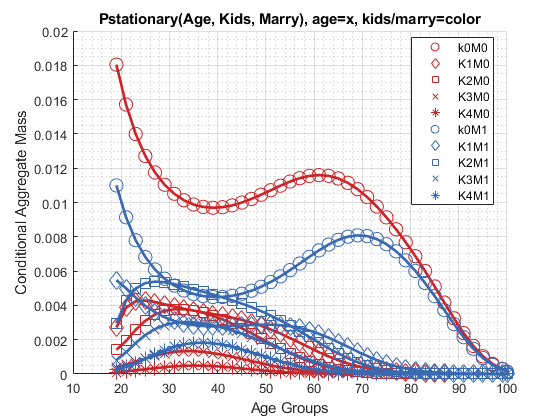

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Kids, Marry), age=x, kids/marry=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = [...
    "k0M0", "K1M0", "K2M0", "K3M0", "K4M0", ...
    "k0M1", "K1M1", "K2M1", "K3M1", "K4M1"];
mp_support_graph('cl_scatter_shapes') = {...
    'o', 'd' ,'s', 'x', '*', ...
    'o', 'd', 's', 'x', '*'};
mp_support_graph('cl_colors') = {...
    'red', 'red', 'red', 'red', 'red'...
    'blue', 'blue', 'blue', 'blue', 'blue'};
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
ff_graph_grid((tb_prob_amarrykids{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Probability Mass Asset and Shock Dimensions

Where are the mass at?

% Get the Joint distribution over all states
Phi_true = mp_dsvfi_results('Phi_true');
Phi_true = Phi_true/sum(Phi_true(:));
% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Asset and Shock Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_prob_az = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     sum_shock__1_3957    sum_shock__0_93044    sum_shock__0_46522    sum_shock_0    sum_shock_0_46522    sum_shock_0_93044    sum_shock_1_3957
    _____    ________    _________________    __________________    __________________    ___________    _________________    _________________    ________________

      1             0         0.011023              0.051451              0.094175          0.076596          0.024846            0.0060425           0.00072716   
      2      0.003203       0.00033689             0.0028305             0.0096175           0.01547         0.0067942           0.00037263           8.1396e-0

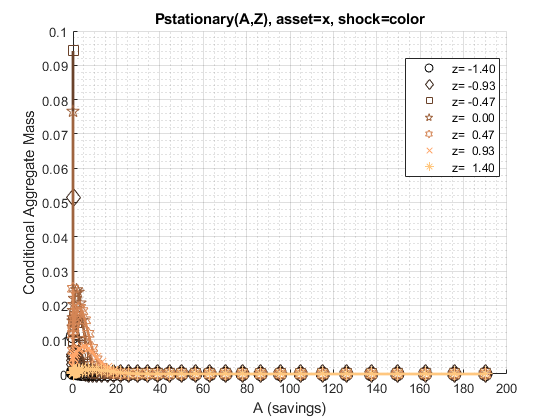

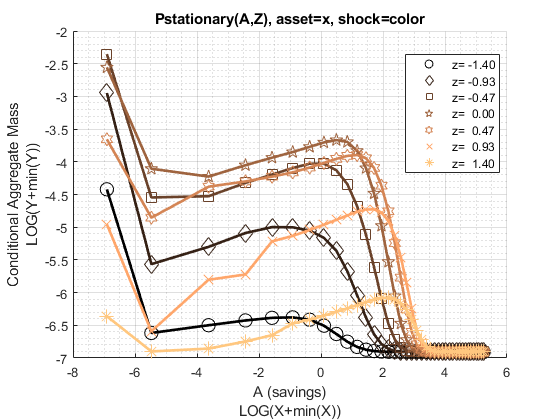

mp_support_graph('cl_st_graph_title') = {'Pstationary(A,Z), asset=x, shock=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.2f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_az{1:end, 3:end})', eta_grid, agrid, mp_support_graph);% Consumption Choices

#### Asset Mass by Age

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [3,4,5,6,1,2];
% Value Function
tb_prob_aage = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     sum_age_19    sum_age_21    sum_age_23    sum_age_25    sum_age_27    sum_age_29    sum_age_31    sum_age_33    sum_age_35    sum_age_37    sum_age_39    sum_age_41    sum_age_43    sum_age_45    sum_age_47    sum_age_49    sum_age_51    sum_age_53    sum_age_55    sum_age_57    sum_age_59    sum_age_61    sum_age_63    sum_age_65    sum_age_67    sum_age_69    sum_age_71    sum_age_73    sum_age_75    

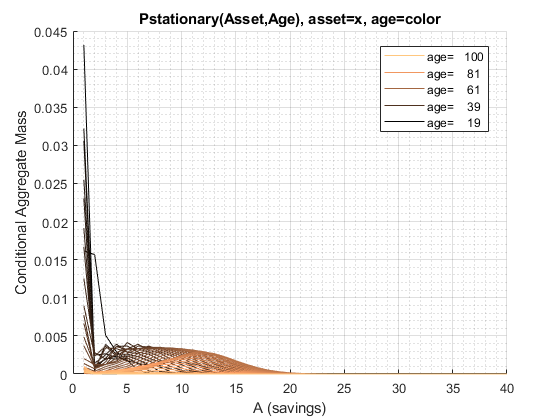

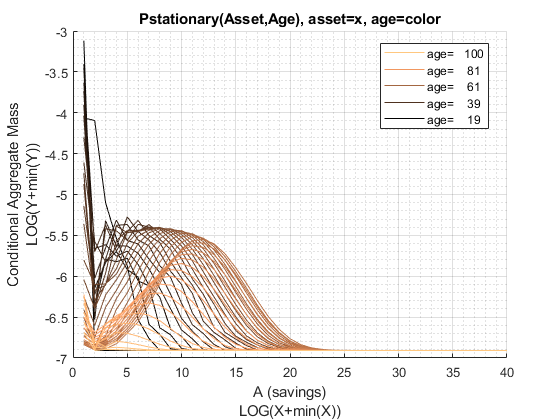

mp_support_graph('cl_st_graph_title') = {'Pstationary(Asset,Age), asset=x, age=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'age=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.0f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_aage{1:end, 3:end})', age_grid, agrid, mp_support_graph);% Consumption Choices

## Probability Statistics A, C and V Conditional on Ages

Where are the mass at?

Phi_true = mp_dsvfi_results('Phi_true');
ap_ss = mp_dsvfi_results('ap_ss');
c_ss = mp_dsvfi_results('c_ss');
v_ss = mp_dsvfi_results('v_ss');
n_ss = mp_dsvfi_results('n_ss');
for it_ctr=1:size(ap_ss, 1)
    if (ismember(it_ctr, round(linspace(1, size(ap_ss, 1), 7))))
        display(['age =' num2str(age_grid(it_ctr))]);
        % construct input data
        Phi_true_age = Phi_true(it_ctr, :, :, : ,: ,:);
        ap_ss_age = ap_ss(it_ctr, :, :, : ,: ,:);
        c_ss_age = c_ss(it_ctr, :, :, : ,: ,:);
        v_ss_age = v_ss(it_ctr, :, :, : ,: ,:);
        n_ss_age = n_ss(it_ctr, :, :, : ,: ,:);
        
        mp_cl_ar_xyz_of_s = containers.Map('KeyType','char', 'ValueType','any');
        mp_cl_ar_xyz_of_s('ap_ss') = {ap_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('c_ss') = {c_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('v_ss') = {v_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('n_ss') = {n_ss_age(:), zeros(1)};
        mp_cl_ar_xyz_of_s('ar_st_y_name') = ["ap_ss", "c_ss", "v_ss", "n_ss"];
        
        % controls
        mp_support = containers.Map('KeyType','char', 'ValueType','any');
        mp_support('ar_fl_percentiles') = [0.01 10 25 50 75 90 99.99];
        mp_support('bl_display_final') = true;
        mp_support('bl_display_detail') = false;    
        mp_support('bl_display_drvm2outcomes') = false;  
        mp_support('bl_display_drvstats') = false;
        mp_support('bl_display_drvm2covcor') = false;
    
        % Call Function     
        mp_cl_mt_xyz_of_s = ff_simu_stats(Phi_true_age(:)/sum(Phi_true_age,'all'), mp_cl_ar_xyz_of_s, mp_support);
    end
end

age =19


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss         v_ss          n_ss   
    _____________________    __________    _________    _________    __________

      {'mean'        }         0.026021      0.65867      -15.331        1.9854
      {'sd'          }         0.069397      0.31614       12.054        1.0848
      {'coefofvar'   }            2.667      0.47996     -0.78622       0.54639
      {'min'         }                0      0.14666      -100.85             1
      {'max'         }           189.83       16.771         13.6             6
      {'pYis0'       }          0.34429            0            0             0
      {'pYls0'       }                0            0      0.93581             0
      {'pYgr0'       }          0.65571            1     0.064189             

age =33


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss          v_ss         n_ss  
    _____________________    _________    _________    __________    ________

      {'mean'        }          0.4686       0.9608        -11.05      2.7227
      {'sd'          }         0.86107      0.45772        10.423      1.4878
      {'coefofvar'   }          1.8375       0.4764      -0.94323     0.54644
      {'min'         }               0      0.20278       -73.845           1
      {'max'         }          189.13       19.369        12.379           6
      {'pYis0'       }         0.34205            0             0           0
      {'pYls0'       }               0            0       0.88023           0
      {'pYgr0'       }         0.65795            1       0.11977           1
      {'pYisMINY' 

age =47


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss          v_ss         n_ss  
    _____________________    __________    _________    __________    ________

      {'mean'        }           1.9484       1.0597       -8.7245      2.5256
      {'sd'          }           2.3541      0.54435        9.2455      1.4583
      {'coefofvar'   }           1.2083      0.51369       -1.0597      0.5774
      {'min'         }                0        0.229       -61.981           1
      {'max'         }           187.73       22.436        10.506           6
      {'pYis0'       }         0.044757            0             0           0
      {'pYls0'       }                0            0       0.82868           0
      {'pYgr0'       }          0.95524            1       0.17132           1
      {'

age =61


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss          c_ss          v_ss          n_ss   
    _____________________    __________    __________    __________    __________

      {'mean'        }           4.4913         1.033       -7.3021         1.928
      {'sd'          }           3.9475        0.5838        7.8249        1.1135
      {'coefofvar'   }          0.87893       0.56516       -1.0716       0.57757
      {'min'         }                0        0.2207       -54.264             1
      {'max'         }           184.39        27.028        8.0057             6
      {'pYis0'       }        0.0039991             0             0             0
      {'pYls0'       }                0             0       0.83046             0
      {'pYgr0'       }            0.996             1       

age =73


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss          v_ss          n_ss   
    _____________________    _________    _________    __________    __________

      {'mean'        }          3.8514      0.92295       -6.4803        1.5858
      {'sd'          }          3.4199      0.56625        6.2471       0.70813
      {'coefofvar'   }         0.88794      0.61353      -0.96402       0.44656
      {'min'         }               0      0.21429       -46.919             1
      {'max'         }          174.57       33.763        5.6087             6
      {'pYis0'       }       0.0077651            0             0             0
      {'pYls0'       }               0            0       0.85747             0
      {'pYgr0'       }         0.99223            1       0.14253             

age =87


xxx tb_outcomes: all stats xxx
    OriginalVariableNames     ap_ss        c_ss         v_ss          n_ss   
    _____________________    ________    ________    __________    __________

      {'mean'        }        0.89083     0.68415       -6.2542         1.489
      {'sd'          }         1.1328     0.43732        4.1948       0.52285
      {'coefofvar'   }         1.2717     0.63922      -0.67071       0.35114
      {'min'         }              0     0.21429       -26.869             1
      {'max'         }         151.39      55.599        2.9644             6
      {'pYis0'       }        0.12966           0             0             0
      {'pYls0'       }              0           0       0.96277             0
      {'pYgr0'       }        0.87034           1      0.037234             1
      {'pYisMINY' 

age =100


xxx tb_outcomes: all stats xxx
    OriginalVariableNames    ap_ss      c_ss          v_ss          n_ss   
    _____________________    _____    _________    __________    __________

      {'mean'        }          0       0.24086        -4.065        1.4801
      {'sd'          }          0      0.047987        0.9537       0.50624
      {'coefofvar'   }        NaN       0.19923      -0.23461       0.34203
      {'min'         }          0       0.21429       -9.9472             1
      {'max'         }          0        201.84       0.99505             6
      {'pYis0'       }          1             0             0             0
      {'pYls0'       }          0             0       0.99999             0
      {'pYgr0'       }          0             1    5.2011e-06             1
      {'pYisMINY'    }          1     